**Oszcillátor lánc normál módusai**

Első lépésként a feladat sajátérték problémára vezető részét oldottam meg. A [http://www.physics.usu.edu/riffe/3750/Lecture%205.pdf](http://www.physics.usu.edu/riffe/3750/Lecture%205.pdf) oldal alapján végeztem el a számításokat. Az állandókat és változókat a feladat leírása alapján határoztam meg:

clear all, close all;

N=1000;
ks=1e+5;    %rugóállandó, [N/m]
m=1e-4;     %[kg]
d=1e-3;     %[m]

Először egy 1000x1000 mátrixot létrehoztam, és a megfelelő indexű elemeinek a megfelelő értékeket írtam bele, majd ennek a mátrixnak kerestem a sajátvektorait, és sajátértékeit. 

Az n-dik sajátvektor $q_{nj}=A \cdot sin\bigg(\frac{n \pi j}{N+1}\bigg)$: és az n-dik sajátérték: $\Omega_n= 2 \cdot \omega |sin\bigg(\frac{n \pi}{2 \cdot (N+1)} \bigg) |$. Ezeket for ciklus segítségével eltároltam mátrixokban, és ez alapján rajzoltam ki a különböző frekvenciákhoz tartozó sajátvektorokat.

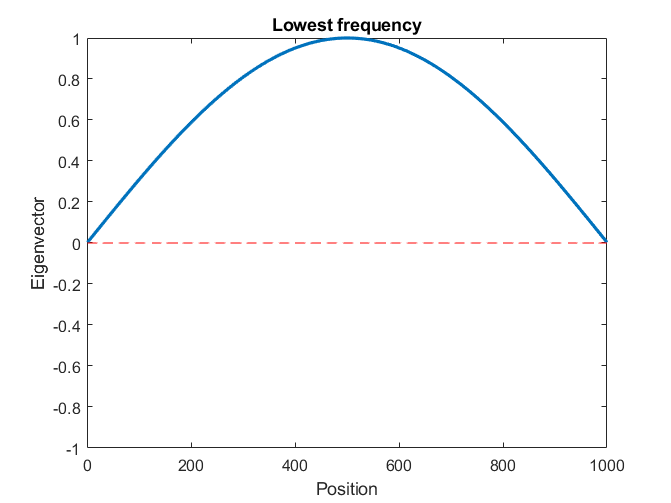

square_of_omega=ks/m;
matrix=zeros(N, N);

for i=1:N
    matrix(i,i)=2*square_of_omega;
    if i-1>0 && i<N+1
        matrix(i-1,i)=-square_of_omega;
    end
    
    if i-1>0 && i<N+1
        matrix(i,i-1)=-square_of_omega;
    end
end

eigenvectors=[];

for j=1:N
    for i=1:N
    eigenvectors(i, j) = (sin(i*j*pi / (N+1)));
    end
end

x=[];
null=[];
for i=1:N
    x=[x i];
    null=[null 0];
end
figure(1);
plot(x, eigenvectors(1:N, 1), 'linewidth', 2)
xlim([0, 1000]);
ylim([-1, 1]);
hold on
plot(x, null, '--r', 'linewidth', 0.02)
xlabel('Position');
ylabel('Eigenvector');
title('Lowest frequency');

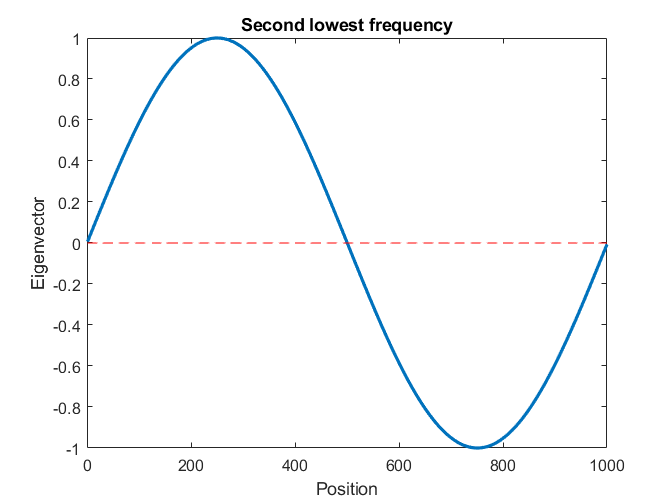


figure(2);
plot(x, eigenvectors(1:N, 2), 'linewidth', 2)
xlim([0, 1000]);
ylim([-1, 1]);
hold on
plot(x, null, '--r', 'linewidth', 0.02)
xlabel('Position');
ylabel('Eigenvector');
title('Second lowest frequency');

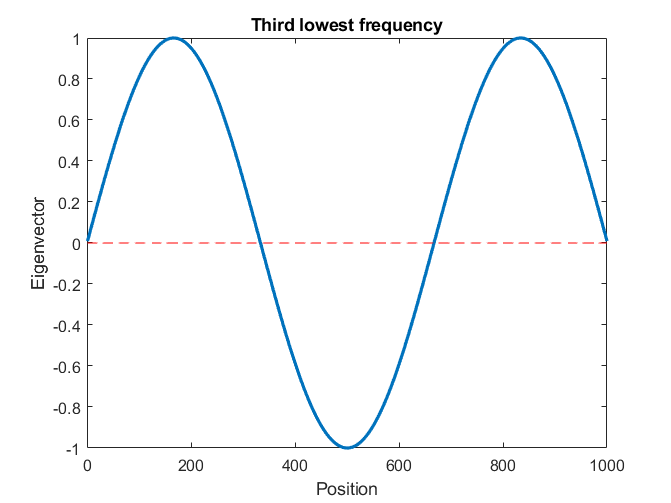


figure(3);
plot(x, eigenvectors(1:N, 3), 'linewidth', 2)
xlim([0, 1000]);
ylim([-1, 1]);
hold on
plot(x, null, '--r', 'linewidth', 0.02)
xlabel('Position');
ylabel('Eigenvector');
title('Third lowest frequency');

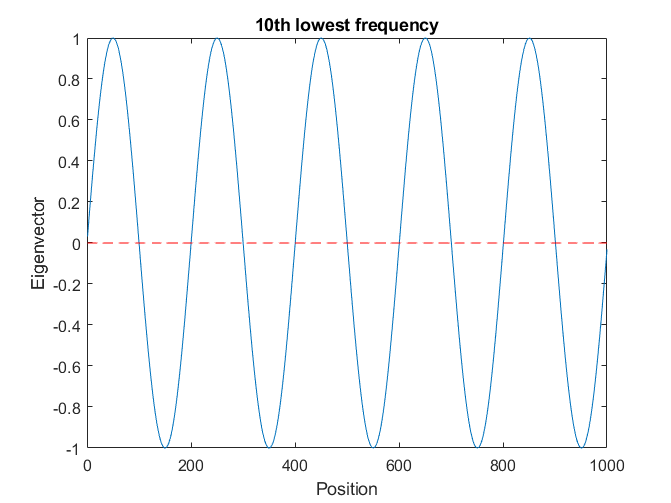


figure(4);
plot(x, eigenvectors(1:N, 10))
xlim([0, 1000]);
ylim([-1, 1]);
hold on
plot(x, null, '--r', 'linewidth', 0.02)
xlabel('Position');
ylabel('Eigenvector');
title('10th lowest frequency');

A következő szekcióban a sajátértékek gyökeit, azaz az oszcillátorok rezgési frekvenciáit ábrázoltam különböző N-ekre.

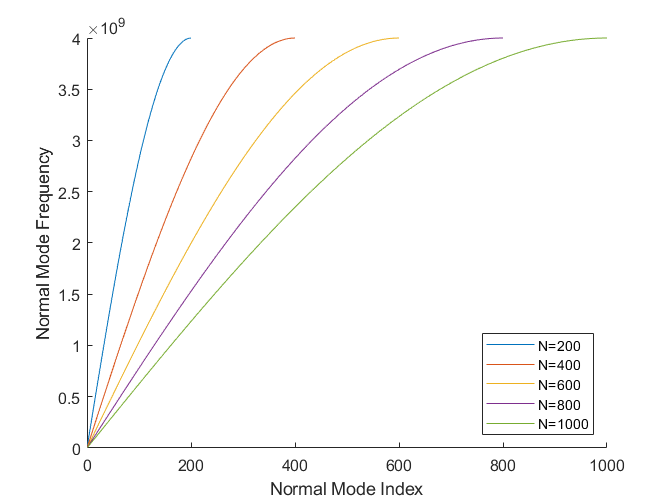

figure(5);
hold on
eigenvalues200=[];
for j=1:200
    eigenvalues200(j)=4*square_of_omega*sin(j*pi / (2*(200+1)));
end
plot([1:200], eigenvalues200)

hold on
eigenvalues400=[];
for j=1:400
    eigenvalues400(j)=4*square_of_omega*sin(j*pi / (2*(400+1)));
end
plot([1:400], eigenvalues400)

hold on
eigenvalues600=[];
for j=1:600
    eigenvalues600(j)=4*square_of_omega*sin(j*pi / (2*(600+1)));
end
plot([1:600], eigenvalues600)

hold on
eigenvalues800=[];
for j=1:800
    eigenvalues800(j)=4*square_of_omega*sin(j*pi / (2*(800+1)));
end
plot([1:800], eigenvalues800)

eigenvalues=[];

for j=1:N
    eigenvalues(j)=4*square_of_omega*sin(j*pi / (2*(N+1)));
end
plot(x, eigenvalues)
xlabel('Normal Mode Index');
ylabel('Normal Mode Frequency')
legend('N=200', 'N=400', 'N=600', 'N=800', 'N=1000', 'Location', 'SouthEast');

Készítette: Bánkövi Orsolya, DAZOJ8